# 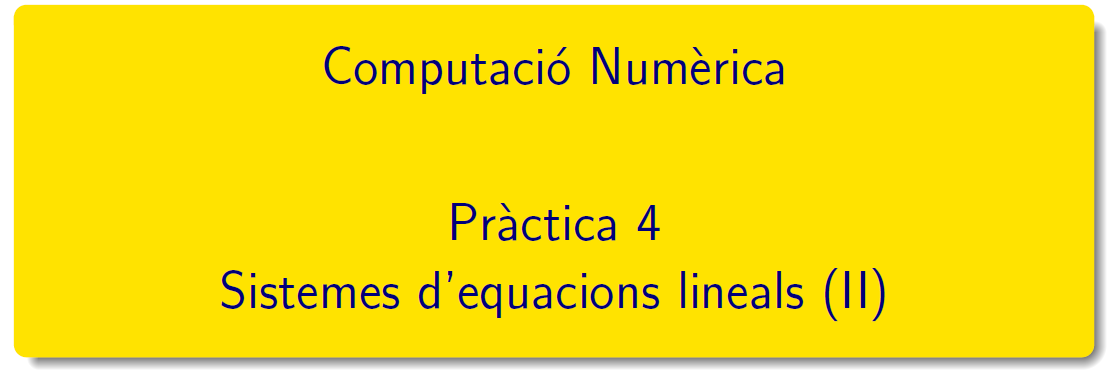

=============================================================================

# Pràctica 4 - Mètodes iteratius

`Document preparat per M. Àngela Grau Gotés, 8 de març de 2023`

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis  en el document CN_full2.pdf, el podeu trobar en el campus virtual. 

**Radi espectral **

Definició i propietats en el document bloc 0 (pàg 16). Càlcul de valors i vectors propis en Matlab®: consulteu [eigs ](https://www.mathworks.com/help/matlab/ref/eigs.html)i [eig](https://es.mathworks.com/help/matlab/ref/eig.html) 

H = hilb(4)

H =     1.0000    0.5000    0.3333    0.2500
    0.5000    0.3333    0.2500    0.2000
    0.3333    0.2500    0.2000    0.1667
    0.2500    0.2000    0.1667    0.1429


vaps = eig(H), rho = abs(eigs(H,1))  % radi = vap de mòdul màxim

vaps =     0.0001
    0.0067
    0.1691
    1.5002


rho = 1.5002

## Mètodes iteratius estacionaris 

Són els mètodes de Jacobi, de Gauss-Seidel i de sobrerelaxació (SOR)


$$Ax=b \Longleftrightarrow x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,.$$


### Submatrius D, L i U de la matriu A

 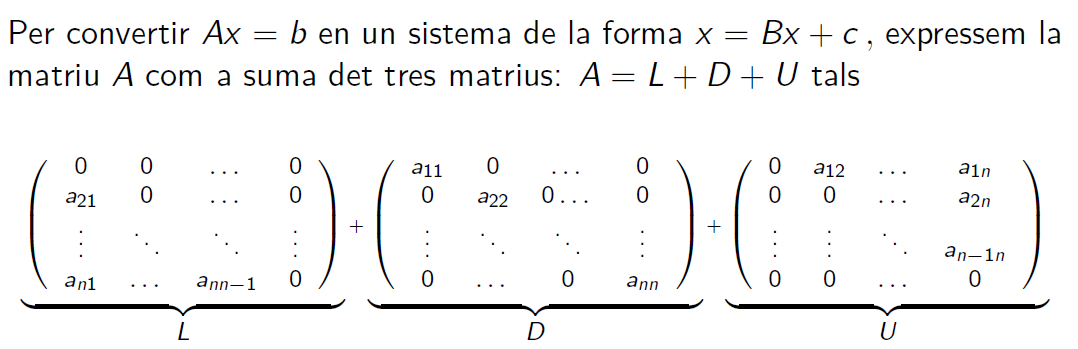     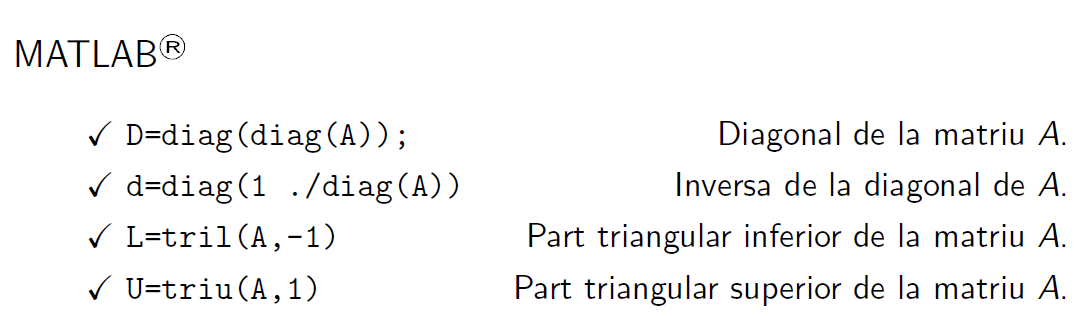

`Exercici 1.`` Obteniu les submatrius L, D, U per a la matriu `$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)$

A = [1 0 1; -1 1 0; 1 2 -3]; b=[4;1;-4];
L = tril(A, -1)

L =      0     0     0
    -1     0     0
     1     2     0


D = diag(diag(A))

D =      1     0     0
     0     1     0
     0     0    -3


U = triu(A, 1)

U =      0     0     1
     0     0     0
     0     0     0


### **Practiquem: Mètodes de Jacobi i de Gauss-Seidel**

`Exercici 2.` `Determineu  les matrius d'iteració del mètode de Jacobi i del mètode de Gauss-Seidel del sistema Ax=b donat per `


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


Matrius de Jacobi:  $ x_{Ji}^{(k+1)} = x_i^{(k)} + \displaystyle\frac{1}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0\,$

Matrius de Gauss-Seidel:  $x_{Si}^{(k+1)} = x_i^{(k)} +\displaystyle \frac{1}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{i-1}a_{ij}x_j^{(k+1)} -\sum_{j=i+1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0$

### **Practiquem: Mètodes de SOR_Jacobi i de SOR_Gauss-Seidel**

`Exercici 3.` `Determineu  les matrius d'iteració del mètode de SOR_Jacobi i del mètode de SOR_Gauss-Seidel del sistema Ax=b donat per `


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


Matrius de SOR-Jacobi:  $ x_{Ji}^{(k+1)} = x_i^{(k)} + \displaystyle\frac{\omega}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0\,$ i per $\omega$ donat, tal que $0<\omega<2$

Matrius de SOR-Gauss-Seidel: $x_{Si}^{(k+1)} = x_i^{(k)} +\displaystyle \frac{\omega}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{i-1}a_{ij}x_j^{(k+1)} -\sum_{j=i}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0$  i per $\omega$ donat, tal que $0<\omega<2$

### Teorema de convergència.

Un esquema iteratiu $x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,$ per a resoldre $Ax=b$ convergeix ssi $\rho(B)<1\,.$

`Exercici 4.`` Verifiqueu el teorema de convergència ``"a priori" ``per als mètodes de Jacobi i Gauss-Seidel`

`Exercici 5. ``Verifiqueu el teorema de convergència ``"a priori" ``per als mètodes SOR per `$0<\omega<2$

#### Exercici 1

Es l'exercici 15 - llista de problemes del tema 2

Escriviu un programa que implementi els algoritmes de Jacobi, Gauss - Seidel i els mètodes SOR amb paràmetre $\omega$. 

- En una primera aproximació determineu les 10 primeres iteracions dels  mètodes i estudieu el vector residu per cada mètode. 

- Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. 

- Proveu-lo per:


$$$$A=\left( \begin{array}{rrrr}
10 & -1 & 2 & 0 \\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)
\qquad
x=\left(\begin{array}{r}   1\\ 2\\-1\\ 1\end{array} \right)$$
$$


clearvars
A = [10 -1 2  0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8], b=[6;25;-11;15];

Mètode de Jacobi

format short

y = [1;2;-1;1]
D = diag(diag(A))
L = tril(A, -1)
U = triu(A,1)
aux = diag(1./diag(A))
JB = -aux*(A-D);
Jc = aux*b;
rhoJ = abs(eigs(JB, 1));

if rhoJ < 1
    fprintf('mètode de Jacobi convergent per rho= %f\n', rhoJ)
    k = 1;
    nb = norm(b,'inf');
    x(:,k) = zeros(size(b));
    %e(k) = norm(x(:,k)-y,'inf');
    r(k) = norm(b-A*x(:,k), 'inf');
    %d(k) = 1;

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


    test = 1;
    while (k<=10 && test > 0.1)
        x(:,k+1) = JB*x(:,k)+Jc;
        %e(k+1) = norm(x(:,k+1)-y,'inf');

y =      1
     2
    -1
     1


        r(k+1) = norm(b-A*x(:,k+1), 'inf');

D =     10     0     0     0
     0    11     0     0
     0     0    10     0
     0     0     0     8


        %d(k+1) = norm(x(:,k+1)-x(:,k), 'inf');

L =      0     0     0     0
    -1     0     0     0
     2    -1     0     0
     0     3    -1     0


        test = r(k+1)/nb;

U =      0    -1     2     0
     0     0    -1     3
     0     0     0    -1
     0     0     0     0


        k = k+1;

aux =     0.1000         0         0         0
         0    0.0909         0         0
         0         0    0.1000         0
         0         0         0    0.1250


    end
    x, r
else
    fprintf('mètode de Jacobi divergent per rho= %f\n', rhoJ)
end

mètode de Jacobi convergent per rho= 0.426437


x =          0    0.6000    1.0473    0.9326
         0    2.2727    1.7159    2.0533
         0   -1.1000   -0.8052   -1.0493
         0    1.8750    0.8852    1.1309


r =    25.0000    7.9182    3.7114    1.2563


Mètode de Gauss-Seidel

clear x e r d
format short
y = [1;2;-1;1]

y =      1
     2
    -1
     1


D = diag(diag(A));
L = tril(A, -1);
U = triu(A,1);
aux = inv(L+D);
GSB = -aux*(U);
GSc = aux*b;
rhoGS = abs(eigs(GSB, 1));

if rhoGS < 1
    fprintf('mètode de Gauss-Seidel convergent per rho= %f\n', rhoGS)
    k = 1;
    nb = norm(b,'inf');
    x(:,k) = zeros(size(b));
    %e(k) = norm(x(:,k)-y,'inf');
    r(k) = norm(b-A*x(:,k), 'inf');
    %d(k) = 1;
    test = 1;
    while (k<=10 && test > 0.1)
        x(:,k+1) = GSB*x(:,k)+GSc;
        %e(k+1) = norm(x(:,k+1)-y,'inf');
        r(k+1) = norm(b-A*x(:,k+1), 'inf');
        %d(k+1) = norm(x(:,k+1)-x(:,k), 'inf');
        test = r(k+1)/nb;
        k = k+1;
    end
    x, r
else
    fprintf('mètode de Gauss-Seidel divergent per rho= %f\n', rhoGS)
end

mètode de Gauss-Seidel convergent per rho= 0.089823


x =          0    0.6000    1.0302
         0    2.3273    2.0369
         0   -0.9873   -1.0145
         0    0.8789    0.9843


r =    25.0000    4.3018    0.3436


Mètode de SOR-Jacobi

Mètode de SOR - Gauss-Seidel

### **Test de parada **

Fixada una tolerància $\epsilon$ l'algoritme s'ha de parar en la iteració $k$ tal que $||e^{(k)}||=||x-x^{(k)}||<\epsilon$

Com que no coneixem $x$, treballem amb el vector residu: $r^{(k)}=b-Ax^{(k)}$ i apliquem el resultat $\displaystyle\frac{||r^{(k)}||}{||b||}<\epsilon
\Longrightarrow
\frac{||e^{(k)}||}{||x||}<\epsilon\,cond(A)$

#### Exercici 2

Joc de proves de l'exercici 15 - llista de problemes del tema 2

Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo per

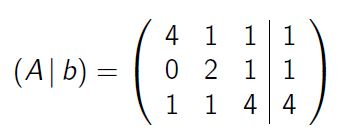     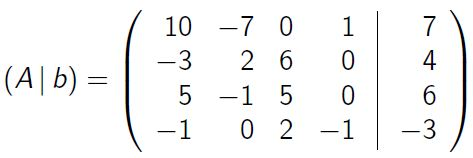      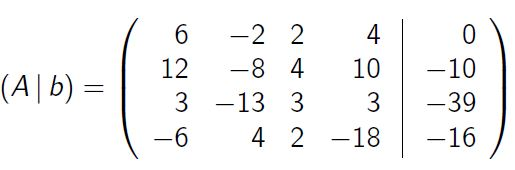

A = [4 1 1; 0 2 1; 1 1 4], b = [1;1;4]; 
% Per fer...

A = [10 -7 0 1;-3 2 6 0; 5 -1 5 0; -1 0 2 -1], b = [7;4;6;-3]; 
% Per fer...

A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18], b = [0; -10; -39; -16]; 
% Per fer...


### Practiquem ...

#### Exercici 3

Es l'exercici 16 - llista de problemes del tema 2

Resoleu pel mètode de Jacobi i de Gauss-Seidel el sistema $Ax=b$ donat per


$$A=\left( \begin{array}{rrrr}
	10 & -1 & 2 & 0 \\
	-1 & 11 & -1 & 3\\
	2 & -1 & 10 & -1\\
	0 & 3 & -1 & 8
	\end{array} \right)\quad\quad
	b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)$$


prenent $x^{(0)}=(0\,,0\,,0\,,0)^{\top}$ i una tolerància $\epsilon = 0.5\cdot 10^{-12}$. Quantes iteracions calen?

Calculeu els errors $\delta^k = ||x^k-x^{k-1}||$ i estudieu $\delta^k/\delta^{k-1}\,.$

% Per fer ... resultats -> exercici3_prac03.html
A = [10 -1 2  0; -1  11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b = [6;25;-11;15];

#### Exercici 4

Determineu el factor $\omega$ per a resoldre


$$\left\{ \begin{array}{rcrcrcrcr}
		10x & + & 5y &  &   &   &    & = & 6\\ %[-0.3em]
		5x & + & 10y &- & 4z &   &   & = & 25\\ %[-0.3em]
	 	   & - & 4y & + & 8z  & - & t  & = & -11\\ %[-0.3em]
		   &  &   & - & z & + & 5t  & = & -11
	\end{array}\right.$$


fent ús dels mètodes de sobrerelaxació variants de Jacobi i de Gauss-Seidel. 

Feu un estudi per $0<\omega<2$. Presenteu els resultats en una taula.

% Per fer ... resultats -> exercici4_prac03.html
A = [10 5 0 0; 5 10 -4 0; 0 -4 8 -1; 0 0 -1 5];
b = [6; 25; -11; -11];

D = diag(diag(A));
L = tril(A, -1);
U = triu(A,1);
aux = diag(1./diag(A));
wx = 0:0.1:2
for k=1:length(wx)
    w = wx(k);
    JwB = -aux*((1-w)*D-w*(L+U));
    Jwc = w*aux*b;
    rhoJw(k) = abs(eigs(JwB, 1));
end
[wx;rhoJw]'
plot(wx,rhoJw,'*'), title('SOR-Jacobi')
hold on
plot(wx,ones(size(wx))),hold off
[rho_O,i] = min(rhoJw), w_o = wx(i)

SOR - Gauss-Seidel

wx = 0:0.1:2
for k=1:length(wx)
    w = wx(k);
    aux = inv(D+w*L);
    JwS = -aux*((1-w)*D-w*U);
    Jwc = w*aux*b;
    rhoSw(k) = abs(eigs(JwS, 1));
end

wx =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


[wx;rhoSw]'
plot(wx,rhoSw,'*'), title('SOR-Gauss-Seidel')
hold on
plot(wx,ones(size(wx))),hold off
[rho_O,i] = min(rhoSw), w_o = wx(i)

#### Exercici 5

Resoleu pels mètodes de classe el sistema $Ax=b$ donat per 


$$A=\left( \begin{array}{rrrr}
		15 & -5 &  0 & -5\\
		-5 & 12 & -2 &  0\\
		0 & -2 &  6 & -2\\
		-5 &  0 & -2 &  9
	\end{array} \right)\quad
	b=\left(\begin{array}{r}   -3.45\\ 9.96\\0\\ 0\end{array} \right)\quad
	x^{*}=\left(\begin{array}{c}   0.14\\ 0.95\\0.37\\ 0.16\end{array} \right)$$


prenent $x^{(0)}=(0\,,0\,,0\,,0)^{\top}$ i una tolerància Quantes iteracions calen?

Calculeu els errors $e^k = ||x^k-x^{\ast}||$,   $\delta^k = ||x^k-x^{k-1}||$ i estudieu $e^k/e^{k-1}\,,\quad$  $\delta^k/\delta^{k-1}\,.$ 

% Per fer ... resultats -> exercici5_prac03.html
clearvars

ans =          0    1.0000
    0.1000    0.9679
    0.2000    0.9359
    0.3000    0.9038
    0.4000    0.8717
    0.5000    0.8397
    0.6000    0.8076
    0.7000    0.7755
    0.8000    0.7434
    0.9000    0.7114


A = [15 -5 0 -5; -5 12 -2 0; 0 -2 6 -2; -5 0 -2 9];
b = [-3.45;9.96;0;0]; y = [0.14;0.95;0.37;0.16]; 

## Mètodes iteratius no estacionaris 

Consulteu en la documentació de MATLAB® - [Iterative Methods for Linear Systems](https://es.mathworks.com/help/matlab/math/iterative-methods-for-linear-systems.html)

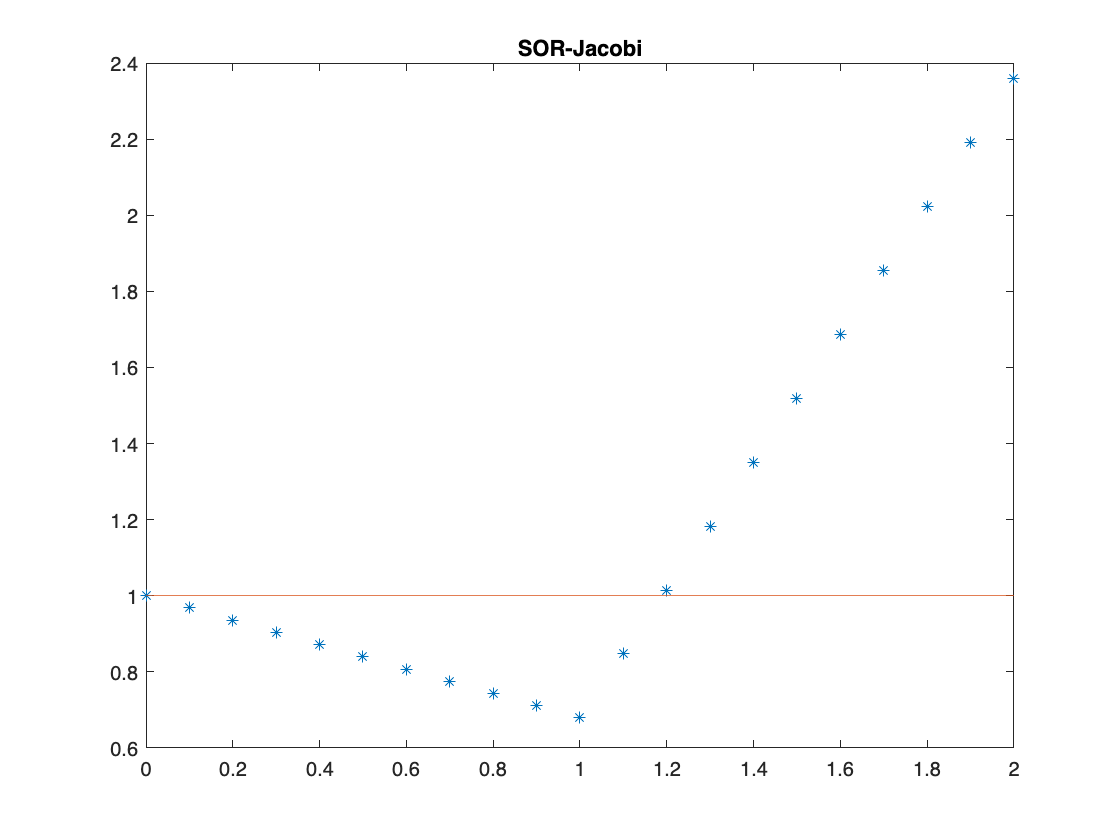

rho_O = 0.6793

i = 11

w_o = 1

wx =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


ans =          0    1.0000
    0.1000    0.9668
    0.2000    0.9311
    0.3000    0.8925
    0.4000    0.8506
    0.5000    0.8047
    0.6000    0.7539
    0.7000    0.6970
    0.8000    0.6320
    0.9000    0.5558


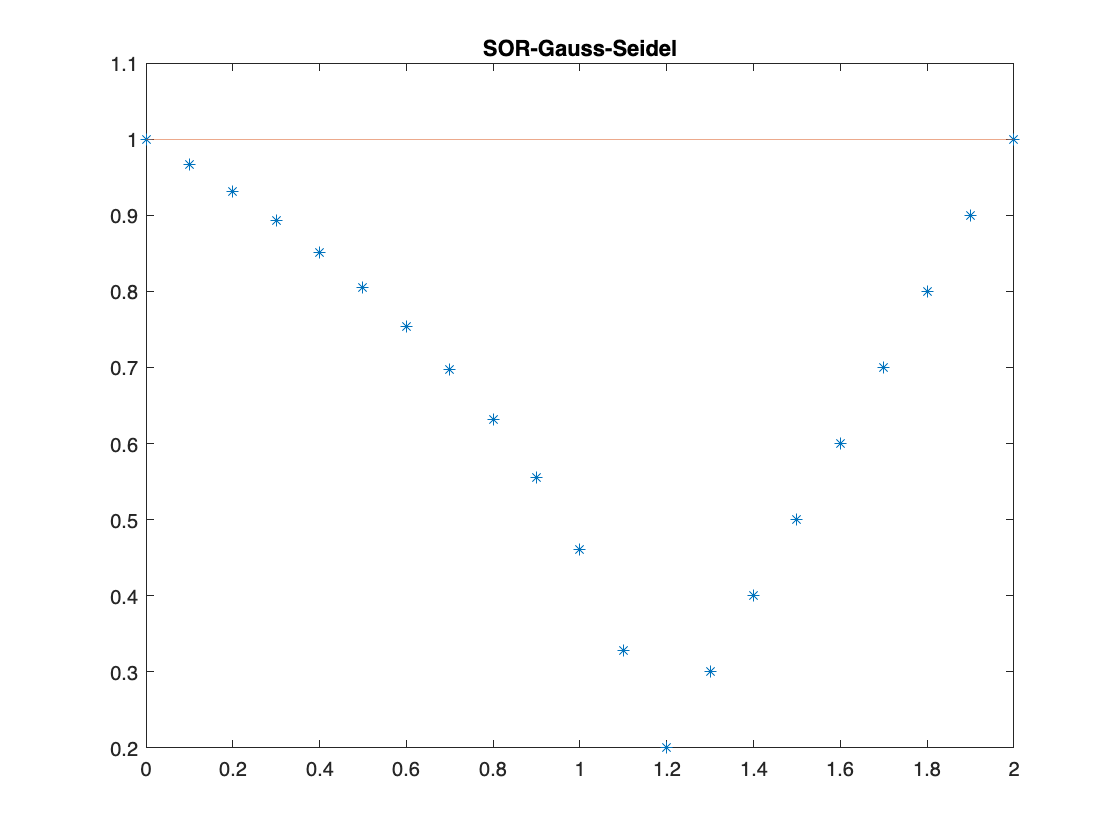

rho_O = 0.2000

i = 13

w_o = 1.2000

`Document preparat per M. Àngela Grau Gotés, 8 de març de 2023`